Class Radarwave test script

*version1.0*

close all;clear;clc;

Set parameters

t1 = 0;
t2 = 1e-3;
fs = 4e7;
f0 = -2e6;
tau = 1e-5;
f_end = 2e6;
PRF = 5e3;
N = 5;
theta = 0;

LFM_Wave

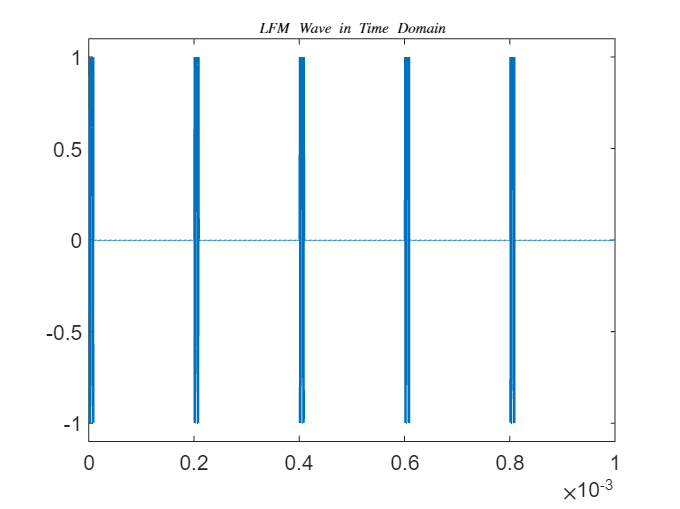

st = Radarbox.LFM_Wave(f0,t1,t2,fs,tau,f_end,PRF,N,theta);
st.LFM_plot();

FMCW

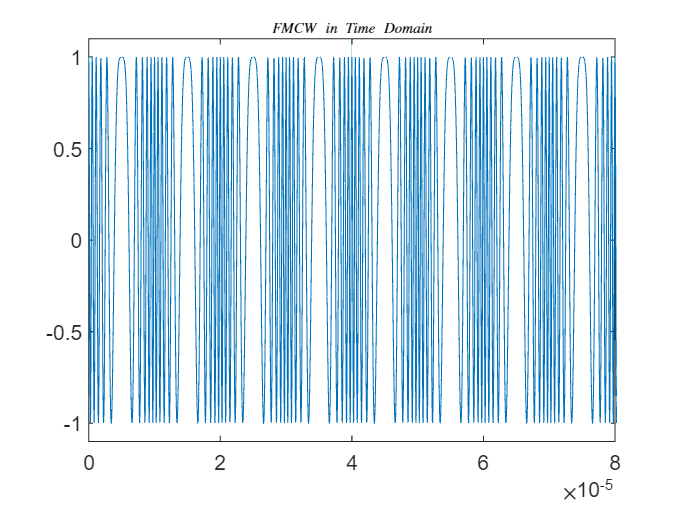

st1 = Radarbox.FMCW_Wave(f0,t1,t2,fs,tau,f_end,N,theta);
st1.FMCW_plot();axis([0,8e-5,-1.1,1.1]);

FMCW with Doppler

vr = 0;
st2 = st.Wave_Rebuild(vr);
st2.LFM_plot();%axis([0,8e-5,-1.1,1.1]);

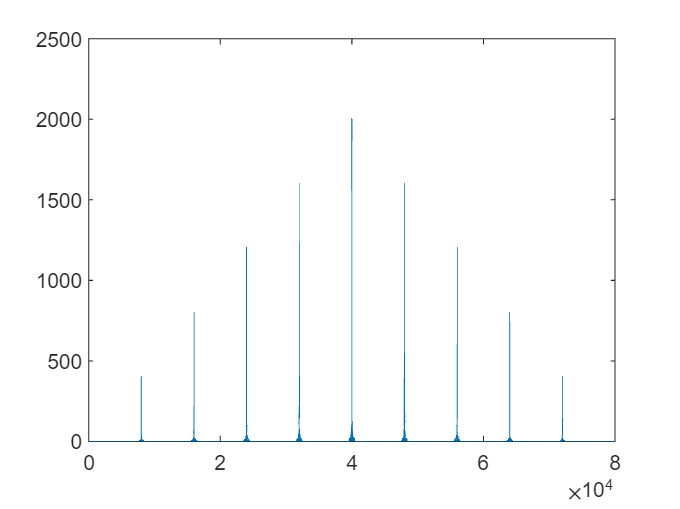

sw = xcorr(st.sigwave,st2.sigwave);
% sw = sw == 0; 
plot(abs(sw));